clear all
close all
path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav";
path1 = path + "\Sasha\Steinway Grand Piano 70.wav";
[y, Fs] = audioread(path1);
z = y(:,1);

clear y

NOTES = 88;


Параметры для изменений

NFFT = 1024;            % Кол-во отчетов для вырезки
N_zero = Fs - NFFT;     % Кол-во нулей после вырезки. Я буде для частотного шага 1Гц
N = floor(2/(NFFT/Fs)); % Количество вырезок за 2 секунды
N_row = N;
ds = 10;                % В сколько раз уменьшить спектр. Минимум 2 - нормально

Заполняю X и Y

data = reshape(z,4*Fs,[]);  % Каждая нота отдельно
data = data(1:N*NFFT, :);   % Каждая нота отдельно Без нулей

Y = zeros(N_row*NOTES, 1);
X = zeros([N_row*NOTES, NFFT+N_zero]);


for k=1:NOTES
    
    N1 = N * (k-1) + 1;
    N2 = N1 + N - 1;
    
    notes = reshape(data(:,k),1024,[])';
    
    X(N1:N2, 1:NFFT) = notes;
    Y(N1:N2) = k;
    
end


cv = cvpartition(Y,'HoldOut',0.30);
trainInds = training(cv);
testInds = test(cv);

XTrain = X(trainInds,:);
YTrain = Y(trainInds);
XTest = X(testInds,:);
YTest = Y(testInds);

clear X

[STest, MTest] = size(XTest);
[STrain, MTrain] = size(XTrain);

vtest = floor(1:MTest/ds);
vtrain = floor(1:MTrain/ds);

XTest_ds = zeros([STest, length(vtest)]);
XTrain_ds = zeros([STrain, length(vtrain)]);

% Get Spectrum. There is no need to get whole spectrum, It can be divided
% by half or more. ds - specifies how spectrum will be divided.
XTest_spec = abs(fft(XTest'))';
XTrain_spec = abs(fft(XTrain'))';

% Get only one part of spectrum, only important samples
XTest_ds(:, vtest) = XTest_spec(:, vtest);
XTrain_ds(:, vtest) = XTrain_spec(:, vtest);

clear XTrain XTest XTest_spec XTrain_spec

tic
Mdl_freq = fitcecoc(XTrain_ds,YTrain);
label = predict(Mdl_freq,XTest_ds);
toc

Elapsed time is 563.827479 seconds.


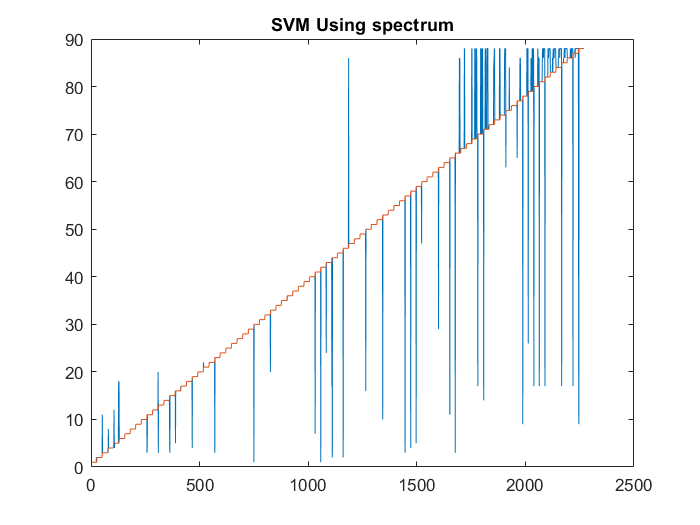


figure
plot(label)
hold on
plot(YTest)
title('SVM Using spectrum')



p = ones([length(label), 1]);
for i = 1:length(p)
    if YTest(i) == label(i)
        p(i) = 0;
    end
end
errors = sum(p)/length(p)

errors = 0.0934